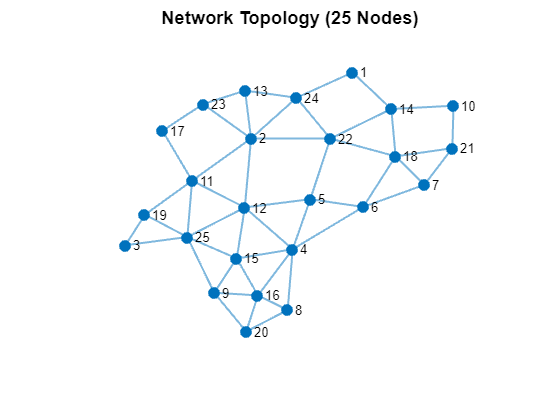

% FLOOD_ROUTING_SIMULATION_OPTIMISED.M  
% -------------------------------------------------------------------------  
% Description:  
%   Simulates packet flooding in a 25-node undirected network with duplicate  
%   detection and congestion monitoring. Tracks packet propagation and  
%   provides visualisation of network behaviour.  
%  
% Key Functionality:  
%   1. Network initialisation from adjacency matrix  
%   2. Packet flooding with TTL management  
%   3. Duplicate detection and management  
%   4. Path tracking and delivery confirmation  
%   5. Congestion analysis and visualisation  
%  
% Parameters:  
%   - TTL: Time-To-Live for packets (default: 10 hops)  
%   - T_max: Simulation duration (default: 20 timesteps)  
%   - packetID: Unique identifier for all packets (default: 2631617)  
%   - Source/Destination: Node 3 to Node 10 by default  
%  
% Created: [DD-MM-YYYY]  
% Last Modified: [DD-MM-YYYY]  
% Author: [Your Name]  
% -------------------------------------------------------------------------

clc; clear all;

% Load network topology
load('network_topology_undirected.mat');  % Must contain 'adjMatrixUndirected'
networkTopology = adjMatrixUndirected;
numNodes = size(networkTopology, 1);

% Parameters
TTL = 10;
T_max = 20;
packetID = 2631617;  % Consistent packet ID for all forwarding

% Create graph object
network = graph(networkTopology);

% Define initial packet
initialPacket = struct('source', 3, 'destination', 10, 'ttl', TTL, 'path', [], 'id', packetID);

% Initialise node structures
nodes(numNodes).packetQueue = {};
for i = 1:numNodes
    nodes(i).packetQueue = {};
    nodes(i).receivedIDs = [];
    nodes(i).congestionLog = zeros(1, T_max);
    nodes(i).arrivalCount = 0;
    nodes(i).duplicateCount = 0;
end
nodes(initialPacket.source).packetQueue{end+1} = initialPacket;

duplicateCount = 0;
destinationDuplicateCount = 0;
delivered = false;
finalPath = [];

% Plot initial topology
layoutType = 'force';
figure('Color', 'w');
plot(network, 'Layout', layoutType, 'LineWidth', 1.2, 'MarkerSize', 6);
title('Network Topology (25 Nodes)');
axis off;


% Time loop
for t = 1:T_max
    disp(['--- Time Step ', num2str(t), ' ---']);
    
    tempQueues = cell(numNodes, 1);  % Store next timestep packets
    
    for nodeID = 1:numNodes
        queue = nodes(nodeID).packetQueue;
        nodes(nodeID).congestionLog(t) = length(queue);  % Log queue length
        
        if isempty(queue)
            continue;
        end
        
        % Process one packet per timestep
        packet = queue{1};
        nodes(nodeID).packetQueue = queue(2:end);
        
        % DUPLICATE CHECK
        if ismember(packet.id, nodes(nodeID).receivedIDs)
            duplicateCount = duplicateCount + 1;
            nodes(nodeID).arrivalCount = nodes(nodeID).arrivalCount + 1;
            nodes(nodeID).duplicateCount = nodes(nodeID).duplicateCount + 1;

            if nodeID == initialPacket.destination
                destinationDuplicateCount = destinationDuplicateCount + 1;
                disp(['Duplicate packet arrived at DESTINATION at t=', num2str(t)]);
            end
            continue;
        end

        % First-time packet
        nodes(nodeID).receivedIDs(end+1) = packet.id;
        nodes(nodeID).arrivalCount = nodes(nodeID).arrivalCount + 1;

        % Decrease TTL and update path
        packet.ttl = packet.ttl - 1;
        packet.path = [packet.path, nodeID];

        if packet.ttl <= 0
            continue;
        elseif nodeID == packet.destination
            if ~delivered
                disp(['Packet reached destination at t=', num2str(t), ' via path: ', num2str(packet.path)]);
                finalPath = packet.path;
                delivered = true;
            end
            continue;
        end

        % Forward to all neighbours
        neighbours = find(networkTopology(nodeID, :) == 1);
        for neighbour = neighbours
            newPacket = packet;                % Copy packet
            newPacket.id = packetID;           % Keep consistent ID
            tempQueues{neighbour}{end+1} = newPacket;
        end
    end

    % Move temp queues to main queues
    for i = 1:numNodes
        nodes(i).packetQueue = [nodes(i).packetQueue, tempQueues{i}];
    end
end

--- Time Step 1 ---
--- Time Step 2 ---
--- Time Step 3 ---
--- Time Step 4 ---
--- Time Step 5 ---
--- Time Step 6 ---
--- Time Step 7 ---


Packet reached destination at t=7 via path: 3  19  11   2  22  14  10


--- Time Step 8 ---


Duplicate packet arrived at DESTINATION at t=8


--- Time Step 9 ---
--- Time Step 10 ---
--- Time Step 11 ---
--- Time Step 12 ---
--- Time Step 13 ---
--- Time Step 14 ---
--- Time Step 15 ---
--- Time Step 16 ---
--- Time Step 17 ---
--- Time Step 18 ---
--- Time Step 19 ---
--- Time Step 20 ---



% -------------------- STATS & REPORTING --------------------
disp(' ');

disp(['Total duplicate packets dropped: ', num2str(duplicateCount)]);

Total duplicate packets dropped: 72


disp(['Number of duplicate packets received at DESTINATION node (' num2str(initialPacket.destination) '): ', num2str(destinationDuplicateCount)]);

Number of duplicate packets received at DESTINATION node (10): 1


disp('--- Node-Level Packet Statistics ---');

--- Node-Level Packet Statistics ---


for i = 1:numNodes
    fprintf('Node %2d: Total Arrivals = %3d | Duplicates = %2d\n', ...
            i, nodes(i).arrivalCount, nodes(i).duplicateCount);
end

Node  1: Total Arrivals =   2 | Duplicates =  1
Node  2: Total Arrivals =   6 | Duplicates =  5
Node  3: Total Arrivals =   3 | Duplicates =  2
Node  4: Total Arrivals =   6 | Duplicates =  5
Node  5: Total Arrivals =   4 | Duplicates =  3
Node  6: Total Arrivals =   4 | Duplicates =  3
Node  7: Total Arrivals =   3 | Duplicates =  2
Node  8: Total Arrivals =   3 | Duplicates =  2
Node  9: Total Arrivals =   4 | Duplicates =  3
Node 10: Total Arrivals =   2 | Duplicates =  1
Node 11: Total Arrivals =   5 | Duplicates =  4
Node 12: Total Arrivals =   6 | Duplicates =  5
Node 13: Total Arrivals =   3 | Duplicates =  2
Node 14: Total Arrivals =   3 | Duplicates =  2
Node 15: Total Arrivals =   5 | Duplicates =  4
Node 16: Total Arrivals =   5 | Duplicates =  4
Node 17: Total Arrivals =   2 | Duplicates =  1
Node 18: Total Arrivals =   5 | Duplicates =  4
Node 19: Total Arrivals =   3 | Duplicates =  2
Node 20: Total Arrivals =   3 | Duplicates =  2
Node 21: Total Arrivals =   2 | Duplicat

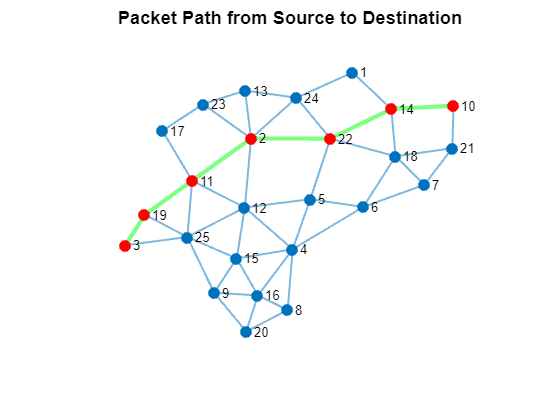


% -------------------- VISUALISE FOUND PATH --------------------
if ~isempty(finalPath)
    figure('Color', 'w');
    h = plot(network, 'Layout', layoutType, 'LineWidth', 1.2, 'MarkerSize', 6);
    highlight(h, finalPath, 'EdgeColor', 'g', 'LineWidth', 2.5);  % Highlight path
    highlight(h, finalPath, 'NodeColor', 'r');
    title('Packet Path from Source to Destination');
    axis off;
end

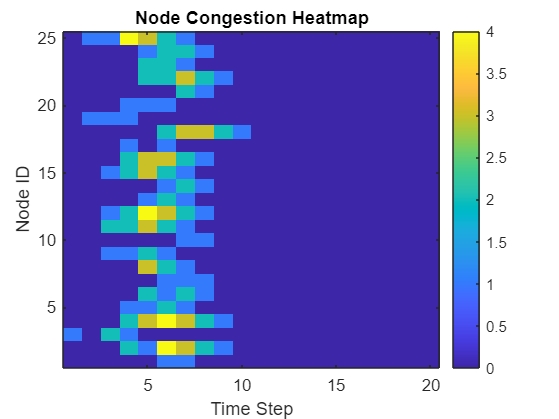


% -------------------- HEATMAP --------------------
congestionMatrix = cell2mat(arrayfun(@(x) x.congestionLog', nodes, 'UniformOutput', false));

figure('Color', 'w');
imagesc(congestionMatrix');
colormap parula;
colorbar;
xlabel('Time Step');
ylabel('Node ID');
title('Node Congestion Heatmap');
set(gca, 'YDir', 'normal');

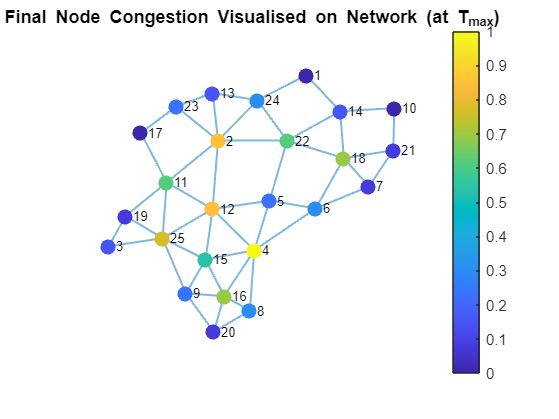


% -------------------- FINAL CONGESTION TOPOLOGY --------------------
finalCongestion = mean(congestionMatrix, 1);      % Take last row (congestion at T_max)
normCongestion = rescale(finalCongestion);       % Already a row vector

figure('Color', 'w');
h = plot(network, 'Layout', layoutType, 'NodeCData', normCongestion, ...
         'MarkerSize', 8, 'LineWidth', 1.2);
colormap parula;
colorbar;
title('Final Node Congestion Visualised on Network (at T_{max})');
axis off;